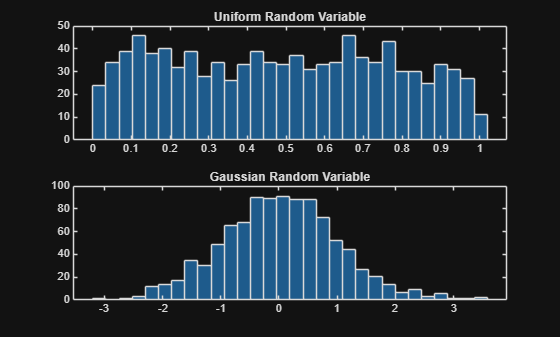

clc;
clear;
close all;

%% ----------------------------------
% 1. Generation of Random Variables
%% ----------------------------------
N = 1000;

% Uniform Random Variable
uniform_rv = rand(1, N);

% Gaussian Random Variable
mu = 0; sigma = 1;
gaussian_rv = mu + sigma*randn(1, N);

figure;
subplot(2,1,1);
histogram(uniform_rv, 30);
title('Uniform Random Variable');

subplot(2,1,2);
histogram(gaussian_rv, 30);
title('Gaussian Random Variable');


%% ----------------------------------
% 2. Estimation of Mean
%% ----------------------------------
mean_uniform = mean(uniform_rv);
mean_gaussian = mean(gaussian_rv);

disp(['Mean (Uniform): ', num2str(mean_uniform)]);

Mean (Uniform): 0.48883


disp(['Mean (Gaussian): ', num2str(mean_gaussian)]);

Mean (Gaussian): 0.03208


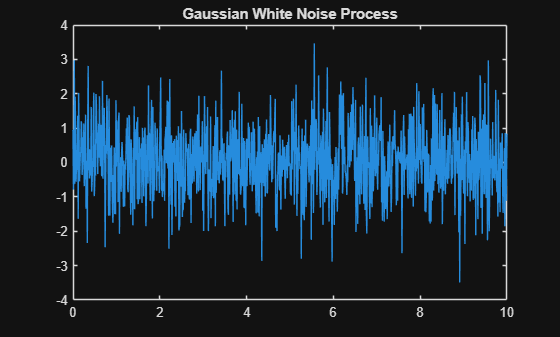


%% ----------------------------------
% 3. Gaussian Process (White Noise)
%% ----------------------------------
t = 0:0.01:10;
white_noise = randn(size(t));

figure;
plot(t, white_noise);
title('Gaussian White Noise Process');

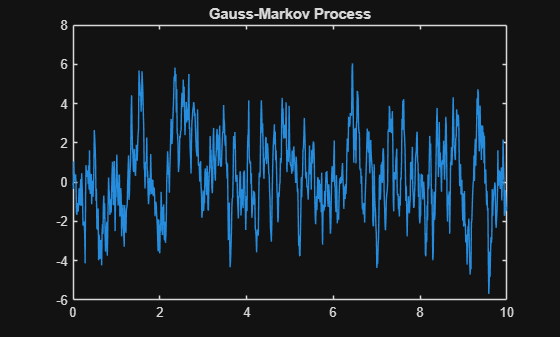


%% ----------------------------------
% 4. Gauss-Markov Process (AR(1))
%% ----------------------------------
a = 0.9;  % correlation coefficient
w = randn(size(t));

gm = zeros(size(t));
for i = 2:length(t)
    gm(i) = a*gm(i-1) + w(i);
end

figure;
plot(t, gm);
title('Gauss-Markov Process');

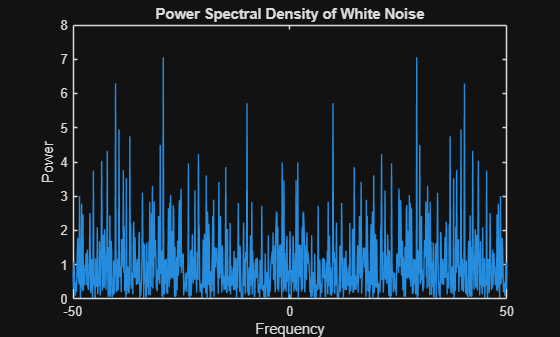


%% ----------------------------------
% 5. Power Spectral Density (PSD)
%% ----------------------------------
Fs = 100; % sampling frequency
Nfft = length(white_noise);

PSD = abs(fftshift(fft(white_noise))).^2 / Nfft;
f = linspace(-Fs/2, Fs/2, Nfft);

figure;
plot(f, PSD);
title('Power Spectral Density of White Noise');
xlabel('Frequency');
ylabel('Power');

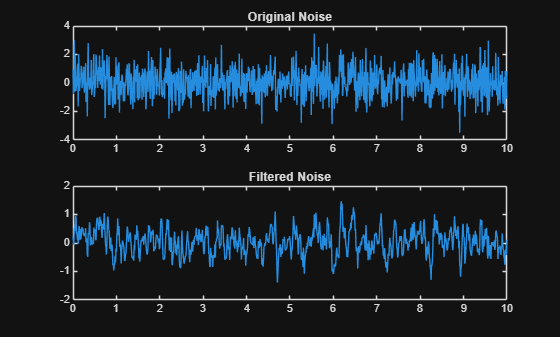


%% ----------------------------------
% 6. Linear Filtering of Random Process
%% ----------------------------------
% Moving Average Filter
b = ones(1,5)/5; % FIR filter
a = 1;

filtered_noise = filter(b, a, white_noise);

figure;
subplot(2,1,1);
plot(t, white_noise);
title('Original Noise');

subplot(2,1,2);
plot(t, filtered_noise);
title('Filtered Noise');

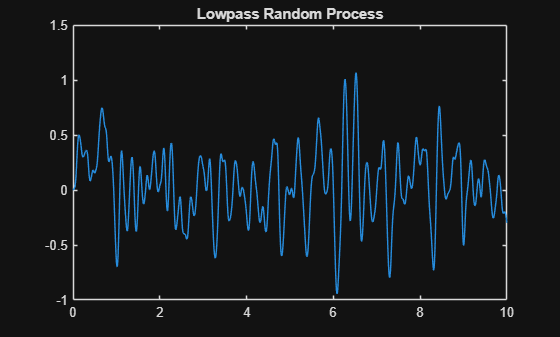


%% ----------------------------------
% 7. Lowpass Process
%% ----------------------------------
fc = 5; % cutoff frequency
[b_lp, a_lp] = butter(4, fc/(Fs/2), 'low');

lowpass_process = filter(b_lp, a_lp, white_noise);

figure;
plot(t, lowpass_process);
title('Lowpass Random Process');

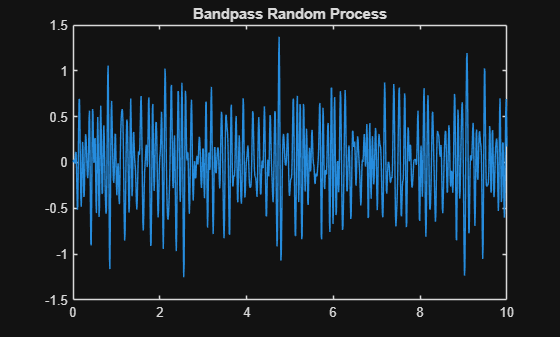


%% ----------------------------------
% 8. Bandpass Process
%% ----------------------------------
f1 = 5; f2 = 15;
[b_bp, a_bp] = butter(4, [f1 f2]/(Fs/2), 'bandpass');

bandpass_process = filter(b_bp, a_bp, white_noise);

figure;
plot(t, bandpass_process);
title('Bandpass Random Process');

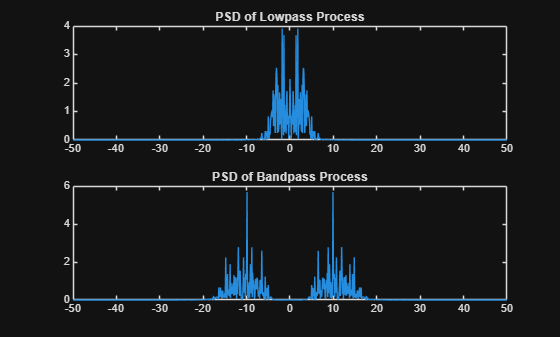


%% ----------------------------------
% 9. PSD of Filtered Signals
%% ----------------------------------
PSD_lp = abs(fftshift(fft(lowpass_process))).^2 / Nfft;
PSD_bp = abs(fftshift(fft(bandpass_process))).^2 / Nfft;

figure;
subplot(2,1,1);
plot(f, PSD_lp);
title('PSD of Lowpass Process');

subplot(2,1,2);
plot(f, PSD_bp);
title('PSD of Bandpass Process');